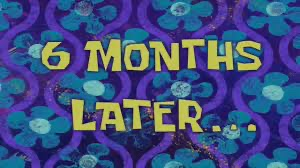

Una vez se extendió el contrato empezamos a trabajar en la identificación del modelo. En aras de establecer el trabajo preliminar para la automatización de este proceso empleamos las funciones del toolbox `systemIdentification` para la ventana de comandos.

## Preprocesamiento

Comenzamos preprocesando los nuevos datos con una serie de funciones de elaboración propia. Primero, verificamos la normalidad de los datos de entrada decidir que métodos de análisis de outliers vamos a incorporar.

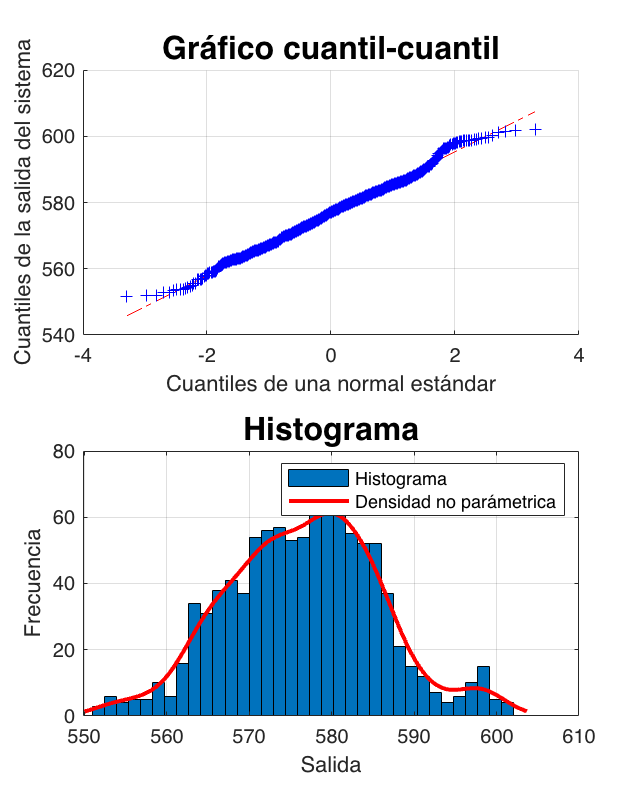

ans = struct with fields:
       ad: {'Anderson-Darling'  'H1'  'H0: Normalidad con enfasis en las colas.'}
       jb: {'Jarque-Bera'  'H0'  'H0: Mean and Variance of normal distriution.'}
     chi2: {'Chi-square goodness-of-fit'  'H1'  'H0: Mean and Variance of normal distriution.'}
    alpha: 0.0500


clear
load DataP1ModExp/data1f.mat
checkGaussian1d(y, 0.05)

Se obtuvieron las mismas conclusiones que para los datos pasados, por lo tanto, se descartan los métodos de amputación de outliers para datos gaussianos. Parece ser que los datos de salida son los mismos puesto que el análisis de datos atípicos llevó a los mismos resultados, es decir, rechazamos la existencia de estos en los datos de salida.

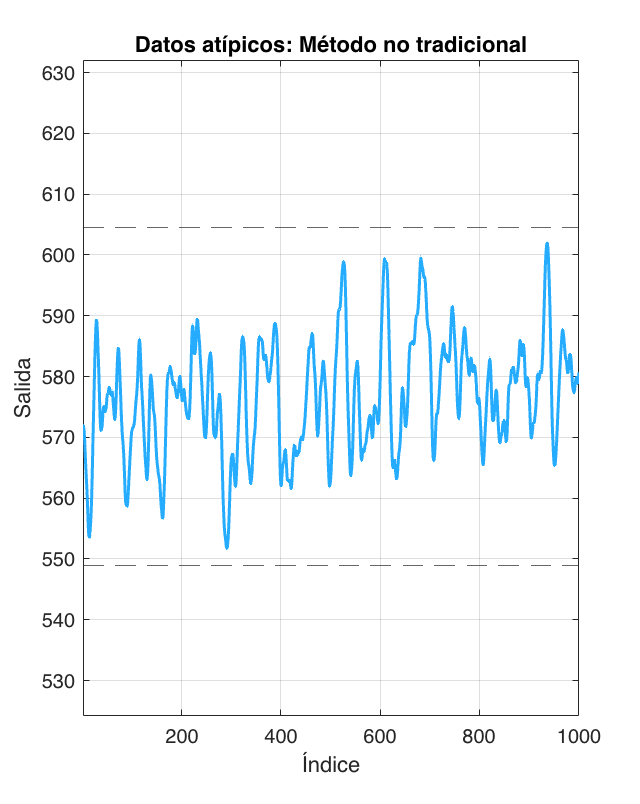


ans =

  1×0 empty double row vector



plot_outliers(y, 'mean')

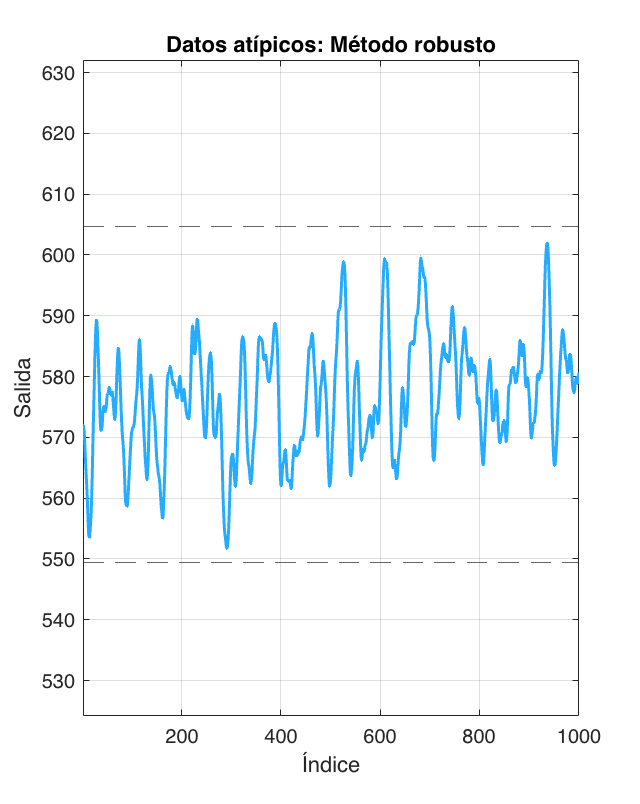


ans =

  1×0 empty double row vector



plot_outliers(y, 'median')

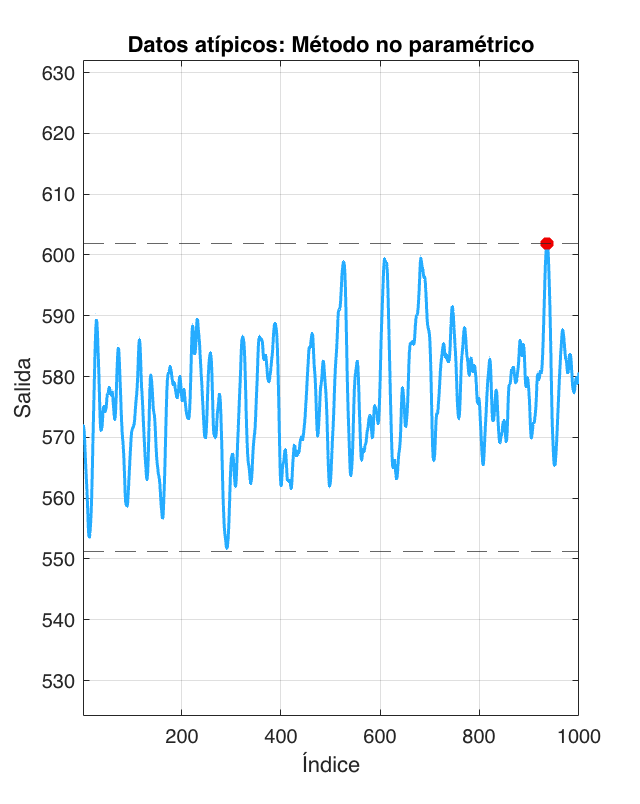

ans =    936   937


plot_outliers(y, 'quartile')

Centrando la atención sobre la entrada, se observa un cambio de escala respecto a la anterior en la PRBS, sin embargo, las estimaciones del orden son idénticas al caso anterior. La única diferencia que resalta a la vista es observable a partir de la función de elaboración propia` params_prbs`, la cual indica que las frecuencias empleadas son sucesivas del 1 al 9.

pexcit(iddata(y', u', 1))

ans = 50

params_prbs(u)

ans = struct with fields:
        n: 1001
    A_max: 1120
    A_min: 900
    order: 9
     freq: [1 2 3 4 5 6 7 8 9]


Ahora, se procede a emplear la función personal `preprocessing_iddata`, la cual simula el preprocesamiento del *quick start *de la aplicación del toolbox `systemIdentification`. Nótese, la única variable que cambió fue $u$, por lo tanto, empleamos los parámetros estimados por el ingeniero anterior, debido a que como vimos en el informe anterior, eran correctos.

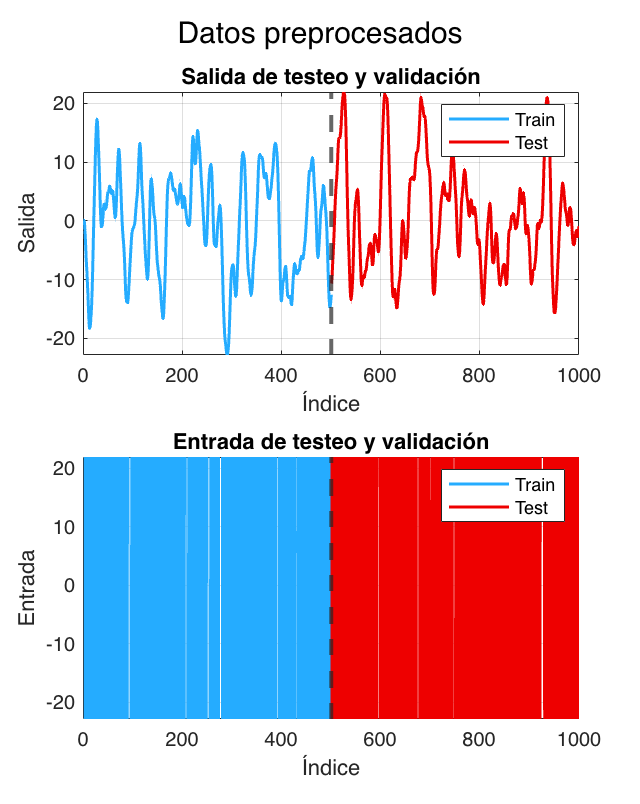

[data, train, test] = preprocessing_iddata(y, u, 1);

## Métodos no paramétricos

### Análisis de autocorrelación

Comenzamos realizando un análisis de autocorrelación, para estimar el retardo. Lo anterior se realiza mediante la función `correlation_impulse`, elaborada por cuenta propia. A partir de la gráfica de respuesta al impulso podemos observar que para un nivel de significancia de $0.001$ el retardo es $d=1$. Por lo tanto, $n_k = 2$, valor que concuerda con la estimación de la función `delayest`.

**Nota:** De ahora en adelante, todos los intervalos de confianza tendrán este nivel de significancia, suponiendo normalidad sobre los errores .

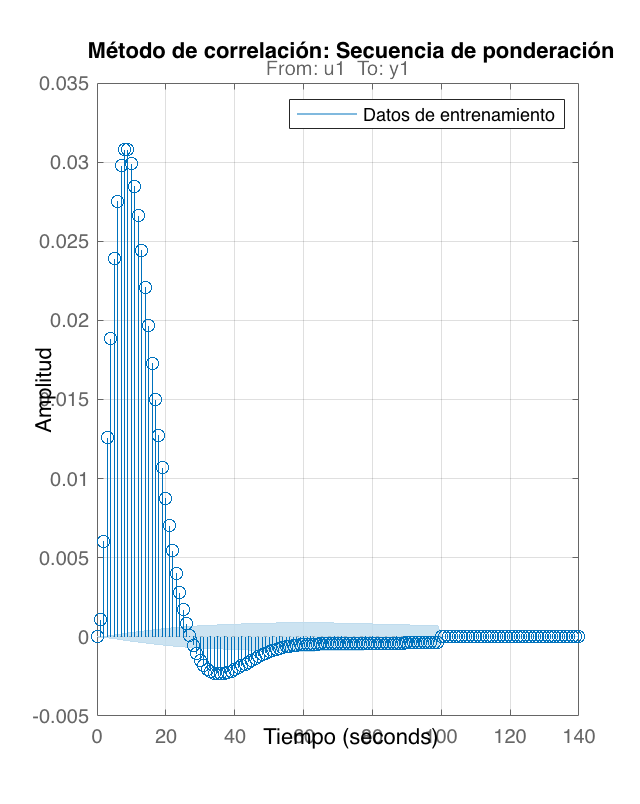

clf
correlation_impulse(train, 100, 0.001)

delayest(train) 

ans = 2

## Modelo espectral

Por su parte, a partir del modelo espectral podemos realizar un diagrama de bode, el cual realizamos con la función personal `spectral_freq_response`. A partir del diagrama observamos que tenemos un comportamiento ideal, puesto que una vez caen las curvas no se evidencia un ruido considerable. Es decir, los datos no requieren ser filtrados, lo cual es valida con el preprocesamiento efectuado.

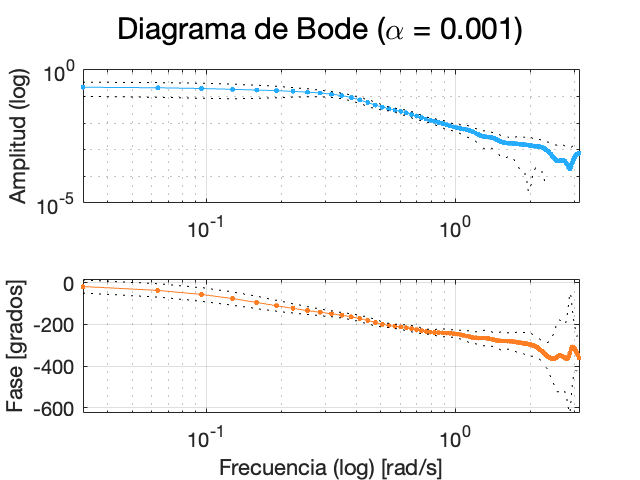

spectral_freq_response(train, 100, 0.001)

## Modelos I-O Polinomiales

Se realizó una exploración extensiva de todos los modelos disponibles en el toolbox: ARX, ARMAX, ARX por VI, OE y BJ. No obstante, solo mostraremos los resultados más importantes, estos solo involucran modelos ARX (tradicional y por variable instrumental). En aras de contribuir a la eventual optimización del procedimiento efectuado en este trabajo, se realizó una función `best_ARX`, la cual explora todos los posibles modelos dentro de un grid establecido por el usuario y escoge las mejores estimaciones considerando tres funciones de costo: mejor ajuste, criterio de información de Akaike y MDL. Nótese que la aplicación del toolbox no tiene incorporado esto para variable instrumental.

% https://la.mathworks.com/help/ident/ref/struc.html
[ARX_bestfit, ARX_AIC, ARX_MDL] = best_ARX(train, test, 1:10, 1:10, 0:2, 'arx');

'train' requires one of the following:
  Deep Learning Toolbox
  Reinforcement Learning Toolbox

[IV_bestfit, IV_AIC, IV_MDL] = best_ARX(train, test, 1:10, 1:10, 0:2, 'iv');

Variando $n_a$ y $n_b$ entre 1 y 10, y el retardo $n_k$ de 0 a 2 (considerando la estimación por métodos no paramétricos), la función nos retorna las mejores estimaciones por cada criterio.

## Validación

Para validar los modelos escogidos, comenzamos comparando las estimaciones de los modelos paramétricos con las respuestas asociadas a los modelos no paramétricos, todos  presentaron un comportamiento aceptable, es decir, no hay un criterio de selección a partir de esta comparación y por tanto para ahorrar espacio no se ponen las gráficas.

### Respuesta temporal

Ahora, a partir del ajuste observamos que los métodos por variable instrumental tienen un peor ajuste. aunque preservan la forma de la respuesta temporal. Vale la pena mencionar, que los mismos modelos en la aplicación del toolbox entregaba un mejor ajuste, en efecto, para variable instrumental oscilaba alrededor del 85% y para el ARX 96%, no obstante, la relación de orden entre modelos es la misma. Se destaca que la diferencia en el ajuste entre los modelos por ARX es mínima.

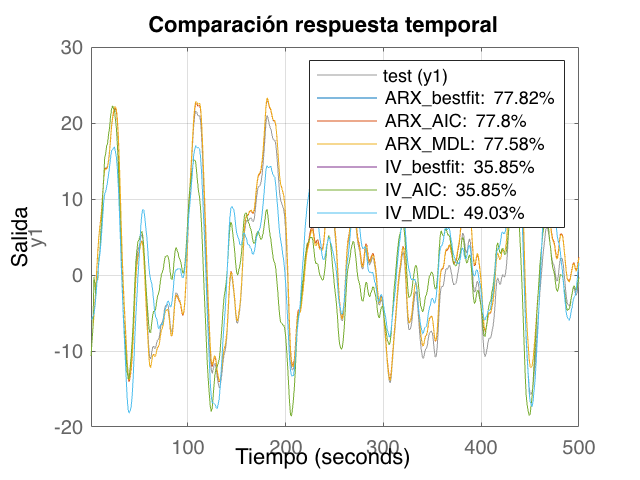

clf
compare(test, ARX_bestfit, ARX_AIC, ARX_MDL, IV_bestfit, IV_AIC, IV_MDL);
grid on
ylabel('Salida'); title('Comparación respuesta temporal'); xlabel('Tiempo')

### Correlación de los residuales

Antes de definir como ganador a la estimación por ARX validamos si los errores no tienen autocorrelación ni correlación cruzada con la entrada, es decir, observamos si el modelo logra blanquear el error. A partir de la figura podemos observar que los modelos estimados por ARX tienen algunos picos significativos, mientras que los estimados por variable instrumental seleccionados por mejor ajuste y AIC no.

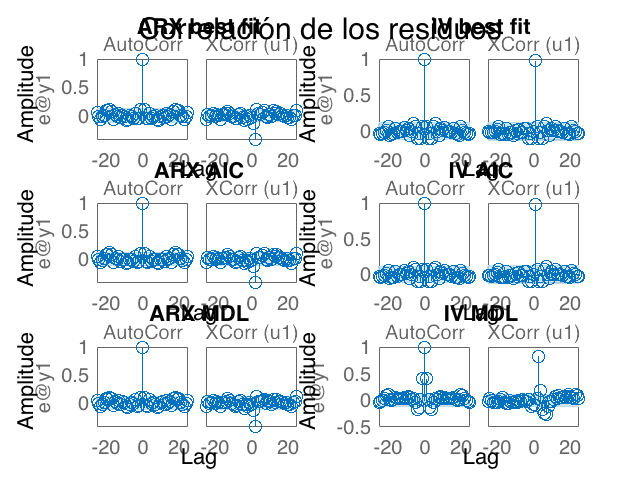

clf
subplot(3, 2, 1)
resid(test, ARX_bestfit)
title('ARX best fit')

subplot(3, 2, 3)
resid(test, ARX_AIC)
title('ARX AIC')

subplot(3, 2, 5)
resid(test, ARX_MDL)
title('ARX MDL')

subplot(3, 2, 2)
resid(test, IV_bestfit)
title('IV best fit')

subplot(3, 2, 4)
resid(test, IV_AIC)
title('IV AIC')

subplot(3, 2, 6)
resid(test, IV_MDL)
title('IV MDL')

sgtitle('Correlación de los residuos')

### Polos y ceros

En aras de observar si hay sustento para reducir el orden de los modelos seleccionados, realizamos un diagrama de polos y ceros con contornos de confianza para cada modelo. A partir de estos se observa que todos los modelos tienen polos y ceros que se pueden cancelar, no obstante, una vez lo hicimos, la correlación de los residuales y el ajuste se deterioró considerablemente, por lo tanto, no fue posible simplificar los modelos. 

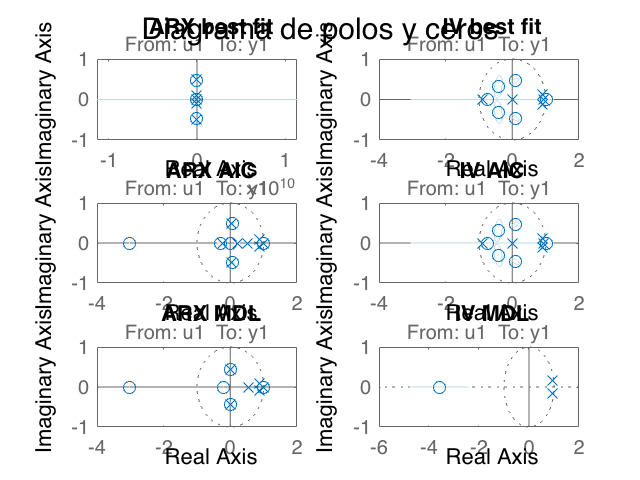

%https://la.mathworks.com/help/ident/ug/refining-linear-parametric-models.html
clf
Alpha = 0.001;
subplot(3, 2, 1)
h = iopzplot(ARX_bestfit); 
showConfidence(h,norminv(1-Alpha))
title('ARX best fit')

subplot(3, 2, 3)
h = iopzplot(ARX_AIC); 
showConfidence(h,norminv(1-Alpha))
title('ARX AIC')

subplot(3, 2, 5)
h = iopzplot(ARX_MDL); 
showConfidence(h,norminv(1-Alpha))
title('ARX MDL')

subplot(3, 2, 2)
h = iopzplot(IV_bestfit); 
showConfidence(h,norminv(1-Alpha))
title('IV best fit')

subplot(3, 2, 4)
h = iopzplot(IV_AIC); 
showConfidence(h,norminv(1-Alpha))
title('IV AIC')

subplot(3, 2, 6)
h = iopzplot(IV_MDL); 
showConfidence(h,norminv(1-Alpha))
title('IV MDL')

sgtitle('Diagrama de polos y ceros')

## Modelo escogido

Claramente no tenemos un modelo dominante, puesto que ARX tiene un ajuste superior con ligeras fallas en la correlación de los residuales mientras que variable instrumental logra blanquear el error. Respecto a los modelos estimados por ARX, escogemos el asociado a la función de costo MDL (ARX 6,6,1), debido a que tiene un ajuste simular a los demás pero un orden menor, es decir, por parsimonia. Nótese, que ninguno de los modelos por ARX consideró un retardo de 2.

Por su parte, entre los modelos estimados por variable instrumental hay un claro ganador: el escogido por mejor ajuste y AIC. Este es un ARX 4, 7, 2, cabe resaltar que aunque este si incorpora el retardo de 2, el orden de la entrada es muy superior al de la salida. Así las cosas escogemos el modelo ARX 6,6,1. 

ARX_MDL

ARX_MDL =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                     
  A(z) = 1 - 3.299 z^-1 + 4.257 z^-2 - 2.865 z^-3 + 1.249 z^-4 - 0.4219 z^-5 + 0.0797 z^-6              
                                                                                                        
                                                                                                        
  B(z) = 0.001095 z^-1 + 0.00243 z^-2 - 0.002671 z^-3 - 0.0001414 z^-4 - 0.0005289 z^-5 - 0.0001391 z^-6
                                                                                                        
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using PEM on time domain data "train". 
Fit to estimation data: 99.96% (prediction focus)
FPE: 1.3

A continuación se muestra la estimación modelo escogido considerando análisis del error: